How big should an claw area be to carry the force transfered

R = 0.1; %m afstand fra axel til claw
T_max = 10000;
% T = F*R
F= T_max/R

F =       100000



Sy = 370; %MPa
% S = F/A
A = F/Sy % mm^2

A =            270.27027027027



A/4 % Area pr teeth for 4 teeth claw coupling

ans =           67.5675675675676



10*10

ans =    100



F = 10*10 * Sy

F =        37000


Internal strain on the coupling due to rotaiton

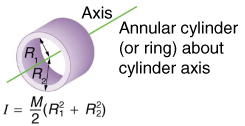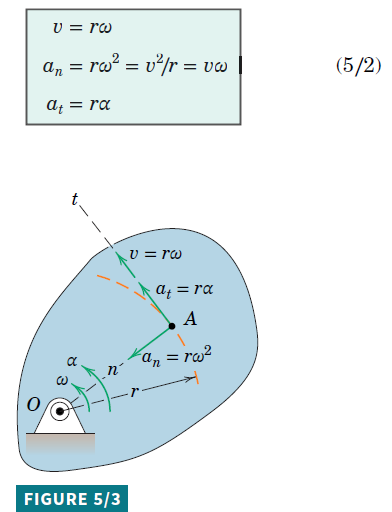

clear all
clf
format longg

g = 9.82;
R2 = 0.25; %m % outer radius 
R1 = 0.0; %m % inner radius 
L = 0.3;
rho = 7800;%kg/m^3 %https://steelnavigator.ovako.com/steel-grades/c45/
V_tooth = 0.010^3;
m_tooth = rho * V_tooth

m_tooth =                     0.0078


m = rho * pi*(R2^2 - R1^2)

m =           1531.52641862502


M = m * L % kg % mass of the slinger part(shoe)

M =           459.457925587507



n = 7200; % rpm % at 120 Hz 
I = M/2 * (R1^2 + R2^2 )

I =           14.3580601746096


E = 200e9; %Youngs modulus
omega = 2 * pi / 60 * n; % rad/s % vinkel hastigheden
a_n = (R2+R2)/2 * omega^2 % Normal acceleration (radialt)

a_n =           142122.303375687


F_n = a_n * M /2

F_n =           32649609.3443557


F_n_tooth = m_tooth * a_n

F_n_tooth =           1108.55396633036


Moment = F_n_tooth * 0.005 

Moment =           5.54276983165178



A = pi*((R2+R1)/2) * L

A =          0.117809724509617


S_max = F_n / A /1e6

S_max =           277.138491582589


S_y = 370

S_y =    370



F_n < S_y

ans = logical
   0


centrifugal stress

S_c = rho * R2^2 * omega^2 /1e6

S_c =           277.138491582589



N_c = 30 * g / (pi*L^2) * sqrt(E*I/m)

N_c =             45117081.27535
